# ROC curves

Pieter Leon van den Berg

22684166

23 October 2022

Final Year Project (C) 478

Supervisor: Dr Cripwell

### Setup

clear;
clc;

### Setup plotting

% Line styles
line_width = 0.8;

% Colours
blue  = '#06ACE9';

## Hotelling's T2

### Read the Hotelling's T2 ROC curve data

% Read the Hotelling's T2 roc curve data
ROC_CURVE_DATA_T2 = load("roc_curves\data\faults_training_roc_curve_T2.mat").ROC_CURVE_DATA_T2

ROC_CURVES_DATA_T2 = 43×3 table
    T2_alpha    true_positive_rate    false_positive_rate
    ________    __________________    ___________________

        1             0.9972                0.99111      
        2            0.98386                0.90316      
        3            0.94341                0.77317      
        4            0.88848                0.66503      
        5            0.84886                0.51764      
        6            0.81879                 0.3508      
        7            0.78924                0.21785      
        8            0.75659                0.14415      
        9            0.72879                0.10684      
       10            0.70417               0.091751      
       11            0.67773               0.084437      
       12            0.65273               0.081844      
       13            0.63348               0.079437  

### Read the Hotelling's T2 true positives rate and false positive rate

% Read the Hotelling's T2 true and false positive rates
T2_true_positives_rate  = flip(ROC_CURVE_DATA_T2.true_positive_rate);
T2_false_positives_rate = flip(ROC_CURVE_DATA_T2.false_positive_rate);

### Calculate the area under the Hotelling's T2 roc curve

% Calculate the area under the Hotelling's T2 roc curve
T2_roc_curve_AUC = trapz(T2_false_positives_rate, T2_true_positives_rate);

## Q statistic

### Read the Q statistic ROC curve data

% Read the Q statistic roc curve data
ROC_CURVE_DATA_Q = load("roc_curves\data\faults_training_roc_curve_Q.mat").ROC_CURVE_DATA_Q

ROC_CURVE_DATA_Q = 40×3 table
    Q_alpha    true_positive_rate    false_positive_rate
    _______    __________________    ___________________

     0.25           0.95189                 0.91158     
      0.5           0.75667                   0.568     
     0.75           0.63083                 0.27812     
        1           0.53992                 0.13462     
     1.25           0.45909                0.073975     
      1.5           0.38197                0.056291     
     1.75           0.32894                0.044255     
        2           0.29227                 0.03046     
     2.25           0.25576                0.025738     
      2.5           0.22485                0.023516     
     2.75            0.1978                0.019535     
        3           0.17871                0.014351     
     3.25           0.16045                0.010925     
      3.5   

## ROC curve

### Plot the Hotelling's T2 and Q statistic ROC curves

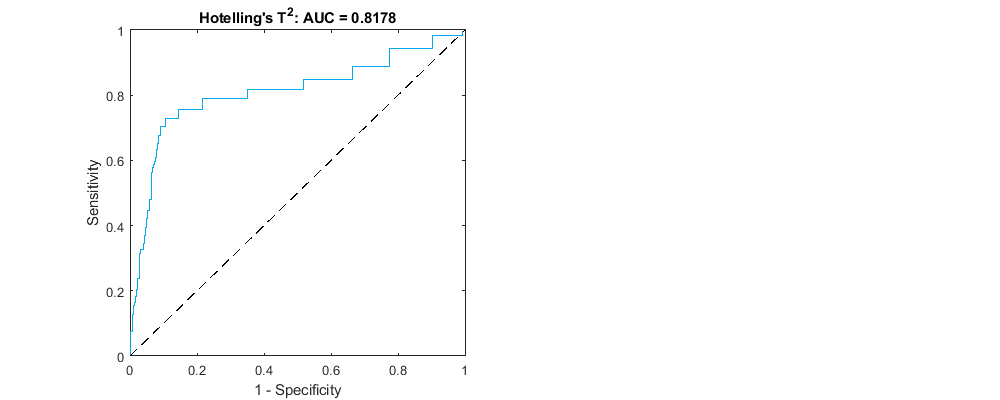

% Create the roc curve figure
figure()

% Plot the Hotelling's T2 roc curve
subplot(1,2,1)
stairs(T2_false_positives_rate, T2_true_positives_rate, 'Color', blue, 'LineWidth', line_width)
hold on
plot([0 1], [0 1], '--k','LineWidth',line_width)
hold off
T2_roc_curve_title = sprintf("Hotelling's T^{2}: AUC = %.04f",T2_roc_curve_AUC);
title(T2_roc_curve_title)
ylabel("Sensitivity")
xlabel("1 - Specificity")
ylim([0 1])
xlim([0 1])
yticks([0, 0.2, 0.4, 0.6, 0.8, 1])
xticks([0, 0.2, 0.4, 0.6, 0.8, 1])

% Set the plot size
fig_scree_plot = gcf;
fig_scree_plot.Position(3:4) = [1000, 400];

% Save the roc curve
print('roc_curves/output/roc_curve', '-dpng', '-r600')